# FFT Example

## Create time domain signal

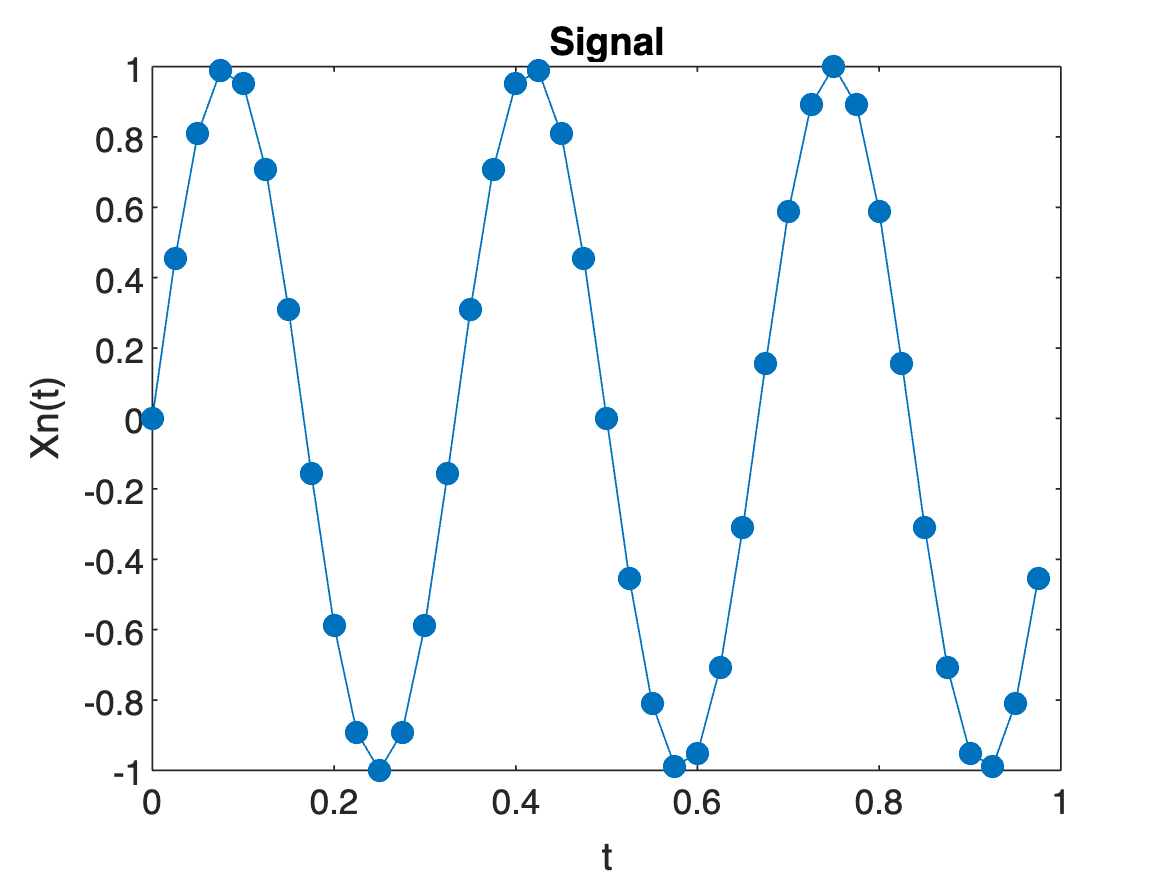

fs = 40;        % Sampling frequency
T = 1/fs;       % Sampling period
N = 40;         % Length of signal
t = (0:N-1)*T';  % Time vector

Xn = sin(2*pi*3*t);       % 3 Hz Signal

plot(t, Xn, '.-', 'MarkerSize', 20);
title("Signal")
xlabel("t")
ylabel("Xn(t)")

## One-sided FFT

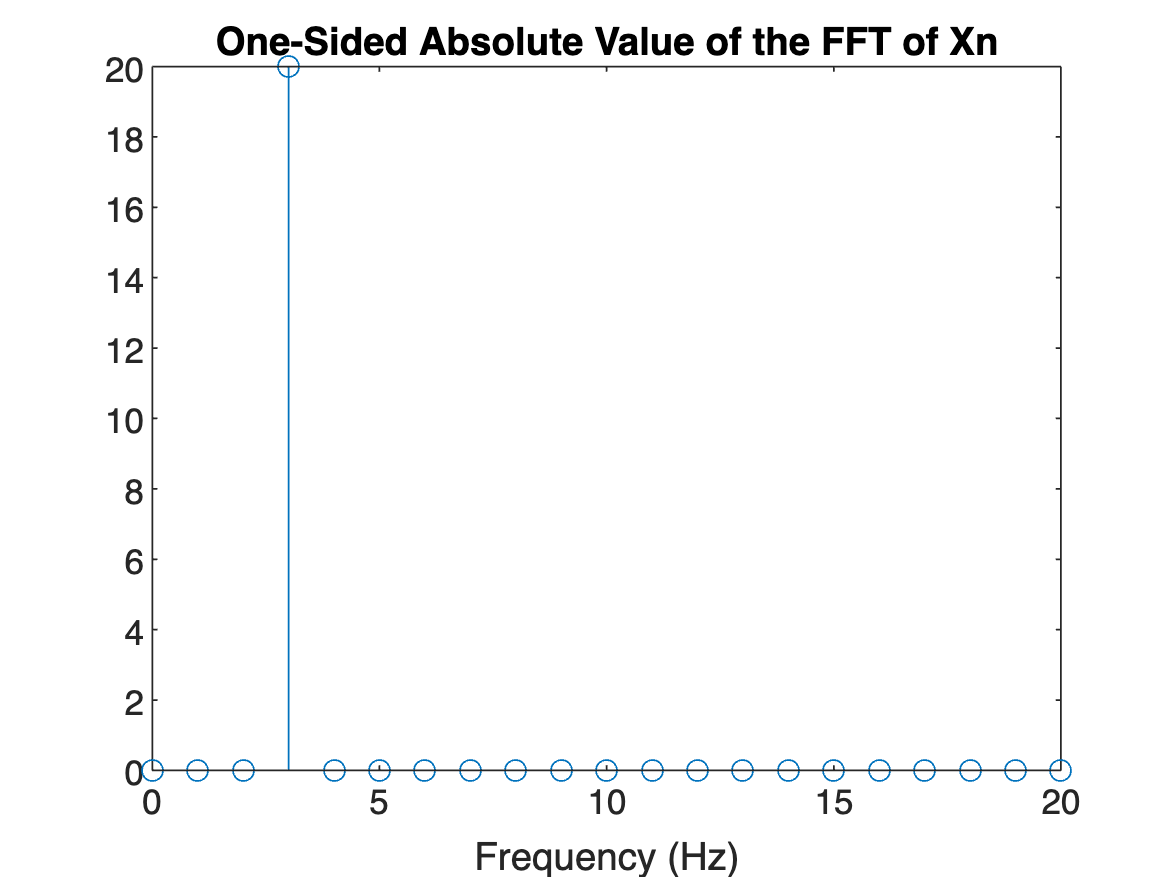

Y = fft(Xn);

k = 0:N/2;      % k starts at 0 so the length of k here is N/2+1
freq = k*fs/N;  % Cycles per length of the signal in seconds

figure
stem(freq, abs(Y(1:(N/2)+1)));
title("One-Sided Absolute Value of the FFT of Xn");
xlabel("Frequency (Hz)");